# PLS Mean Centering

Copyright 2022 Battelle Memorial Institute

## Partial Least Squares (PLS) with Mean Centering

Partial least squares usually uses mean-centered data to compute $C_\textrm{pls}$ using the weights from the SIMPLS algorithm with $r$ latent variables.

## Partial Least Squares (PLS) without Mean Centering

The following is PLS without mean centering.

## Combined algorithm

To make it easier to run with the rest of the tools in the PNNL toolbox, we combined mean-centered and non-mean-centered into one function with `meanCentered` as an optional argument.  When `meanCentered` is not used as an input, then the default is to compute without mean-centered data.

## Napalm Data

Load the included napalm data to run the PLS algorithms.

clearvars
load pnnl_napalm_data
whos

  Name                     Size               Bytes  Class     Attributes

  A_train                 20x1713            274080  double              
  A_unknown               12x1713            164448  double              
  C_train                 20x3                  480  double              
  C_validation            12x3                  288  double              
  ConcentrationUnits       1x4                    8  char                
  ConstituentNames         1x3                  364  cell                
  WavenumberLabel          1x20                  40  char                
  Wavenumbers              1x1713             13704  double              
  ans                      1x1                    8  double              



## Optimal number of latent variables for PLS with mean centering

Compute PLS with mean centering for 1 through 18 latent variables and plot RMSEP for them.

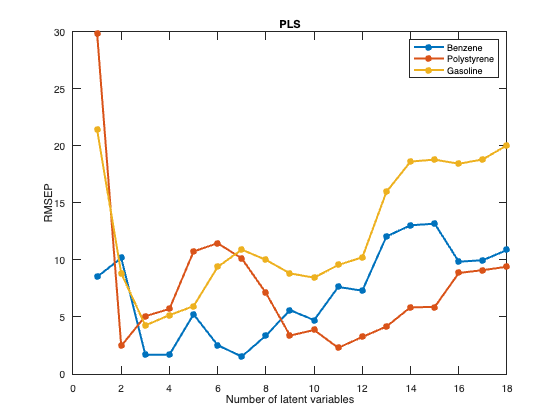

nLatentVariables = 1:18;
meanCentered = true;
[C_pls, RMSEP_pls] = pnnl_napalm_pls(nLatentVariables,meanCentered);
plot(nLatentVariables, RMSEP_pls,'.-','LineWidth',2,'MarkerSize',20)
xlabel('Number of latent variables')
ylabel('RMSEP')
title('PLS')
legend(ConstituentNames{:})

For mean-centered data, it looks like the knee in the curve for polystyrene is 2 latent variables, and 3 for benzene and gasoline.  Plot them to see what they look like.

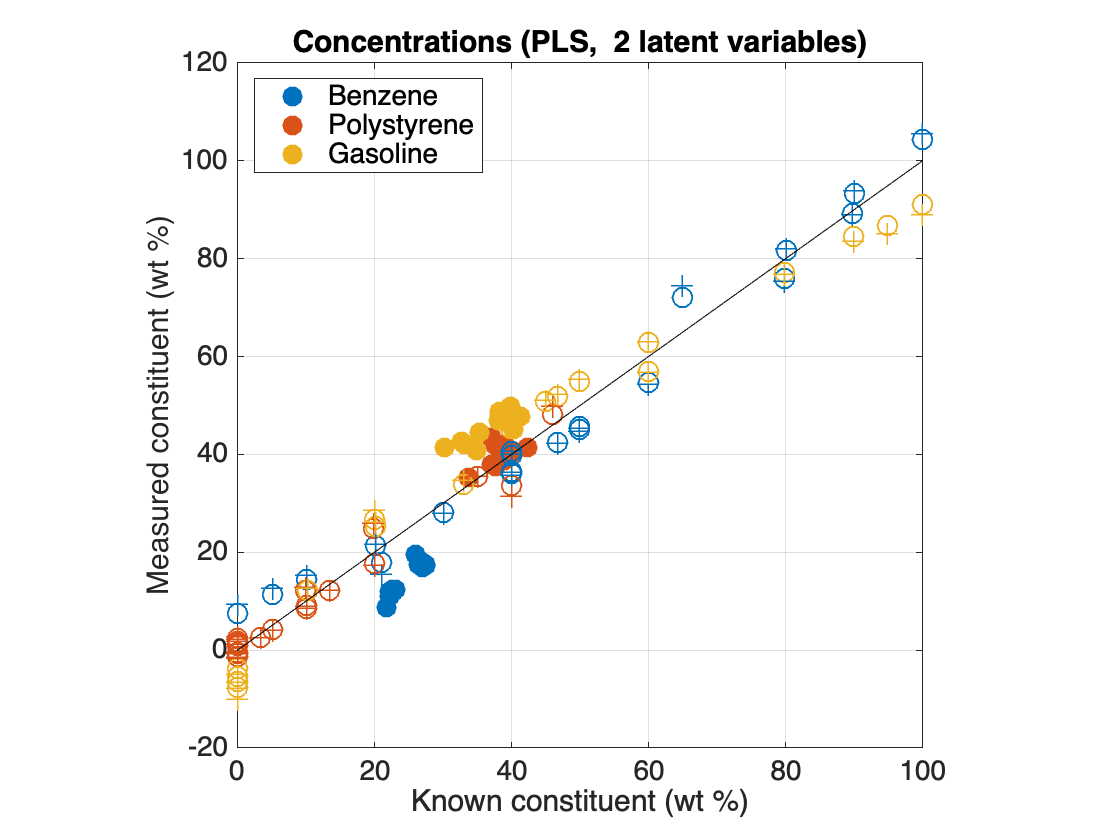

Legend: Dot is predicted. Circle is train. Cross is cross-validation.
--------------------------------------------------------------------
  PLS,  2 latent variables       Benzene   Polystyrene      Gasoline
                     RMSEC        4.1479         2.296        5.5014
                    RMSECV        5.0229         2.924        6.5258
                     RMSEP        10.164        2.4566        8.8266
--------------------------------------------------------------------


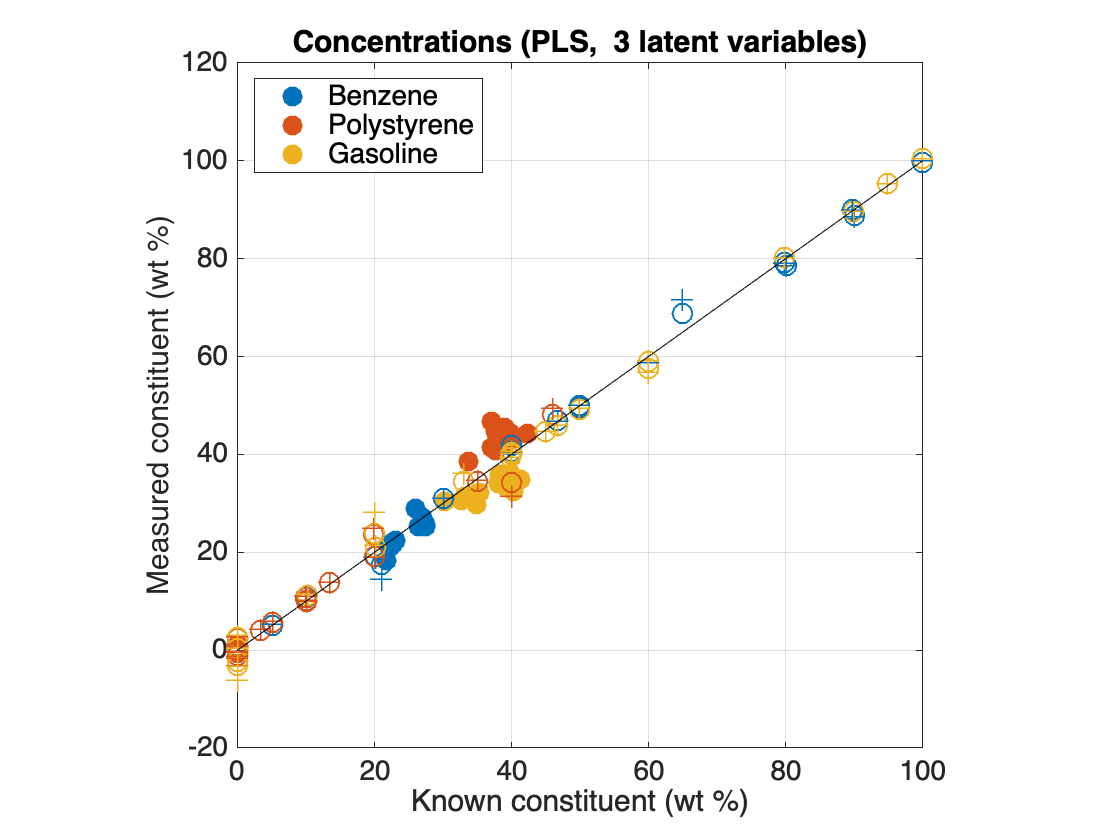

Legend: Dot is predicted. Circle is train. Cross is cross-validation.
--------------------------------------------------------------------
  PLS,  3 latent variables       Benzene   Polystyrene      Gasoline
                     RMSEC        1.3968        1.8465        1.5789
                    RMSECV        2.2406        2.6176        2.7657
                     RMSEP        1.6799        5.0647        4.2528
--------------------------------------------------------------------


nLatentVariables = [2,3]; 
pnnl_napalm_pls(nLatentVariables,meanCentered);

## Optimal number of latent variables for PLS without mean omentering

Compute PLS witout mean centering for 1 through 18 latent variables and plot RMSEP for them.

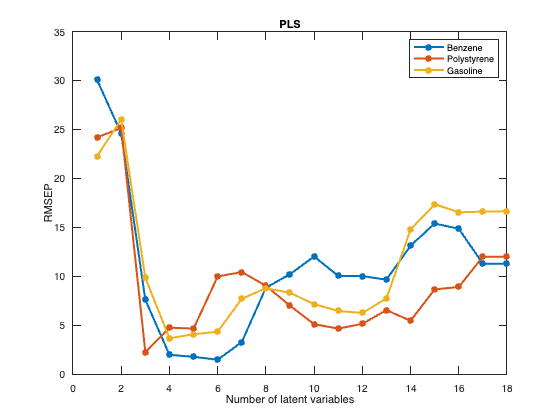

nLatentVariables = 1:18;
meanCentered = false;
[C_pls, RMSEP_pls] = pnnl_napalm_pls(nLatentVariables,meanCentered);
plot(nLatentVariables, RMSEP_pls,'.-','LineWidth',2,'MarkerSize',20)
xlabel('Number of latent variables')
ylabel('RMSEP')
title('PLS')
legend(ConstituentNames{:})

Without mean centering, it looks like the knee in the curve for polystyrene is 3 latent variables, 4 for gasoline, and 6 for benzene.  Plot them to see what they look like.

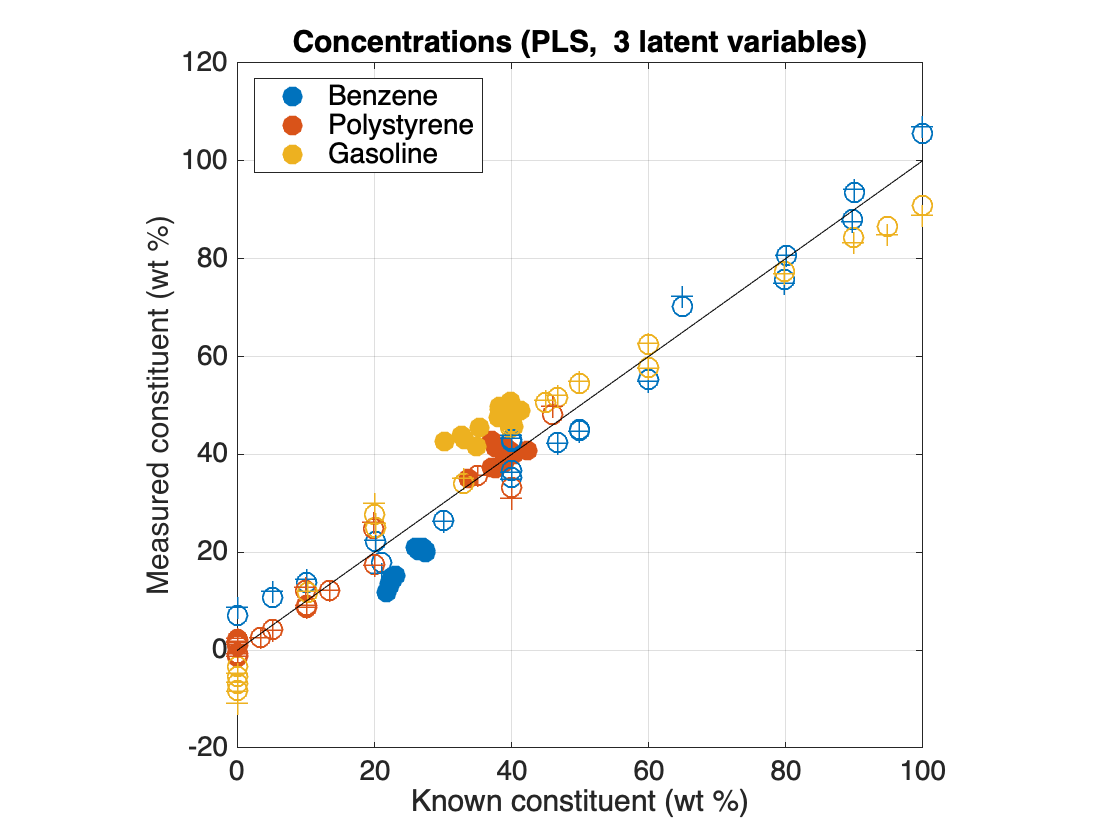

Legend: Dot is predicted. Circle is train. Cross is cross-validation.
--------------------------------------------------------------------
  PLS,  3 latent variables       Benzene   Polystyrene      Gasoline
                     RMSEC        4.1853        2.3592        5.6109
                    RMSECV        5.0232        2.9897        6.6976
                     RMSEP        7.5851        2.2404        9.8369
--------------------------------------------------------------------


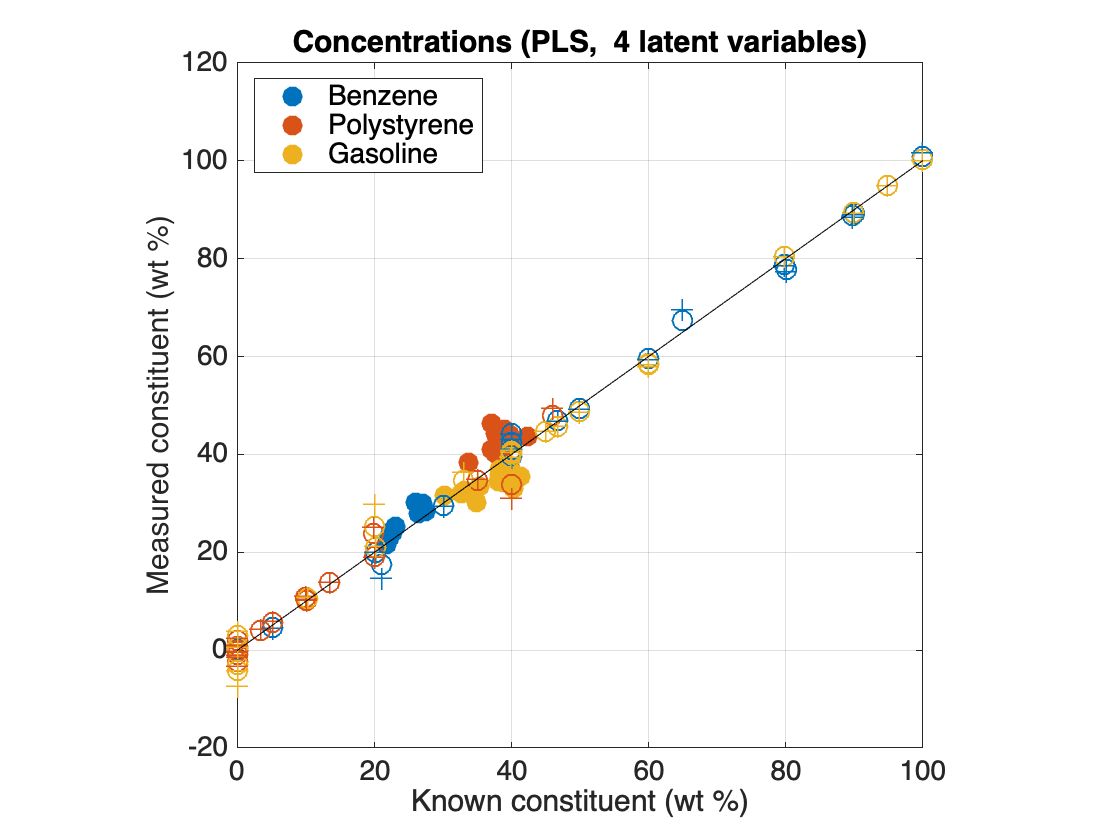

Legend: Dot is predicted. Circle is train. Cross is cross-validation.
--------------------------------------------------------------------
  PLS,  4 latent variables       Benzene   Polystyrene      Gasoline
                     RMSEC        1.6636         1.921        1.9509
                    RMSECV        2.3112        2.6884        3.2095
                     RMSEP        1.9599        4.7379        3.6527
--------------------------------------------------------------------


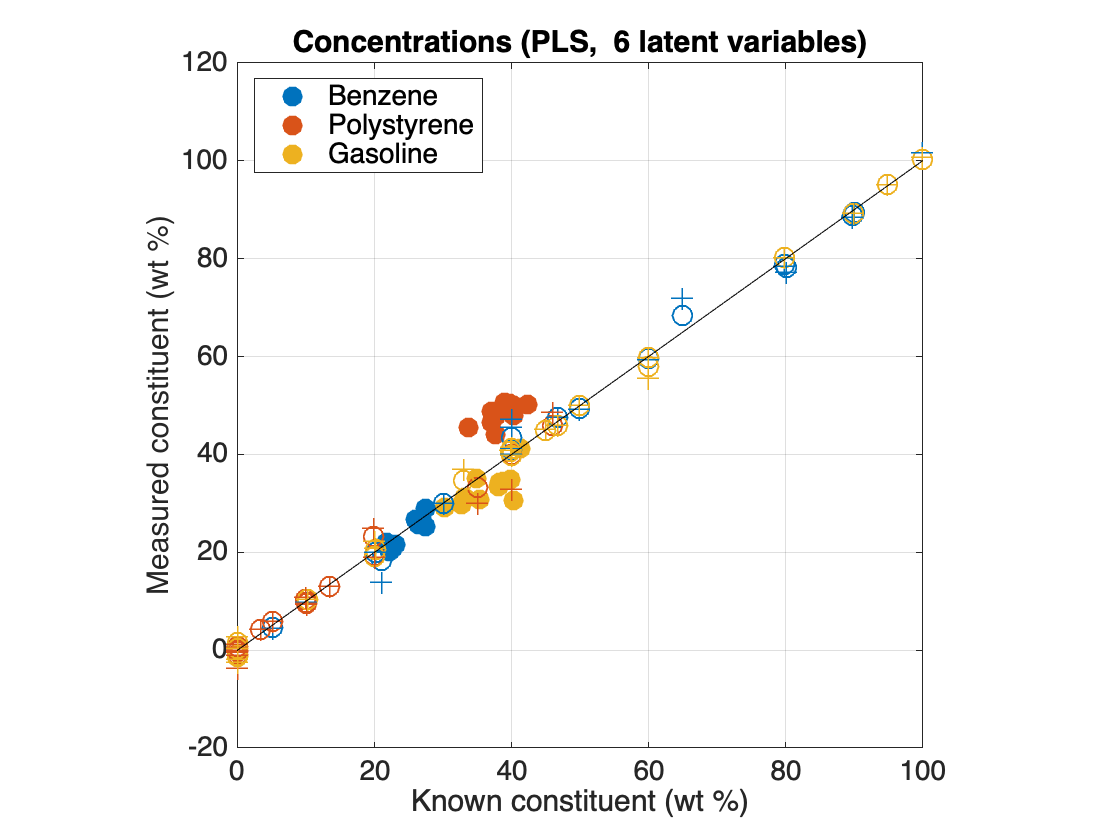

Legend: Dot is predicted. Circle is train. Cross is cross-validation.
--------------------------------------------------------------------
  PLS,  6 latent variables       Benzene   Polystyrene      Gasoline
                     RMSEC        1.4134       0.99256       0.91242
                    RMSECV        3.1544        2.5526        1.7502
                     RMSEP        1.4567        9.9656        4.3211
--------------------------------------------------------------------


nLatentVariables = [3 4 6];
pnnl_napalm_pls(nLatentVariables,meanCentered);

%#ok<*ASGLU> 

Disclaimer

This material was prepared as an account of work sponsored by an agency of the United States Government. Neither the United States Government nor the United States Department of Energy, nor Battelle, nor any of their employees, nor any jurisdiction or organization that has cooperated in the development of these materials, makes any warranty, express or implied, or assumes any legal liability or responsibility for the accuracy, completeness, or usefulness or any information, apparatus, product, software, or process disclosed, or represents that its use would not infringe privately owned rights.

Reference herein to any specific commercial product, process, or service by trade name, trademark, manufacturer, or otherwise does not necessarily constitute or imply its endorsement, recommendation, or favoring by the United States Government or any agency thereof, or Battelle Memorial Institute. The views and opinions of authors expressed herein do not necessarily state or reflect those of the United States Government or any agency thereof.

PACIFIC NORTHWEST NATIONAL LABORATORY

operated by

BATTELLE

for the

UNITED STATES DEPARTMENT OF ENERGY

under Contract DE-AC05-76RL01830